# 矩阵分解

clc;
clear all;
close all;

### 图像压缩

    在图像处理中，矩阵的秩可用于图像压缩和去噪。通过对图像矩阵进行低秩近似，可以减小图像文件大小，同时保持图像的主要特征。

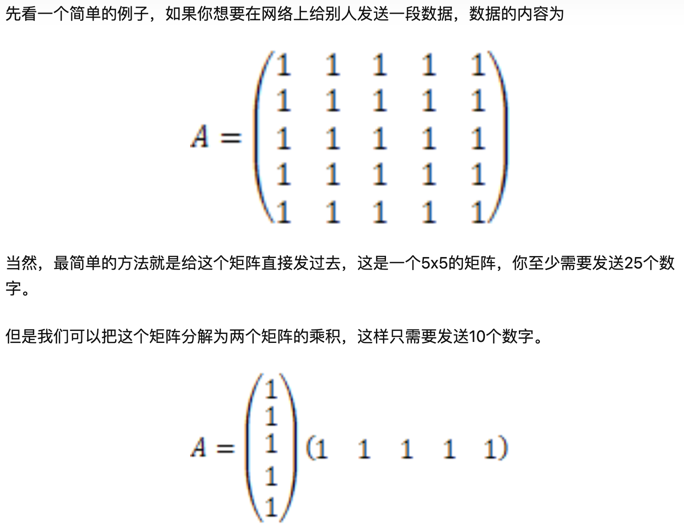

[1] [Python实现奇异值分解（SVD）压缩图片 - 知乎 (zhihu.com)](https://zhuanlan.zhihu.com/p/110020411)

[2] 范云鹏.矩阵低秩逼近在图像压缩中的应用[D].西安电子科技大学,2014.

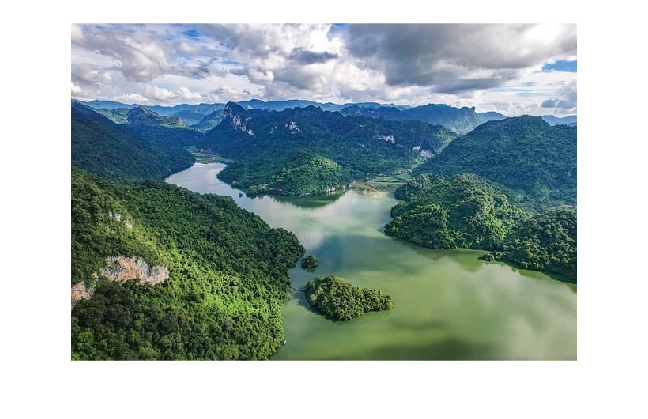

% 读取示例图像
img = imread('IMG_0.JPG');
% 显示原始图像和近似图像
figure;
imshow(img)

size(img)

ans =    427   640     3


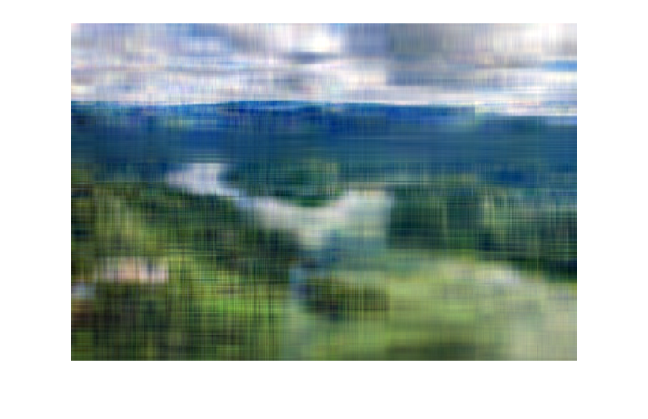


% 分离RGB通道
red_channel = img(:,:,1);
green_channel = img(:,:,2);
blue_channel = img(:,:,3);

% 对每个通道进行SVD分解
[U_red, S_red, V_red] = svd(double(red_channel));
S_red_approx = S_red;
[U_green, S_green, V_green] = svd(double(green_channel));
S_green_approx = S_green;
[U_blue, S_blue, V_blue] = svd(double(blue_channel));
S_blue_approx = S_blue;

% 循环不同的k值
k_values = [100, 30, 10];
for i = 1:length(k_values)
    k = k_values(i);
    % 选择前k个最大的奇异值
    S_red_approx(k+1:end, k+1:end) = 0; 
    S_green_approx(k+1:end, k+1:end) = 0; 
    S_blue_approx(k+1:end, k+1:end) = 0;

    % 重建近似通道
    red_approx_channel = U_red * S_red_approx * V_red';
    green_approx_channel = U_green * S_green_approx * V_green';
    blue_approx_channel = U_blue * S_blue_approx * V_blue';

    % 合并三个通道得到近似RGB图像
    approx_img = cat(3, uint8(red_approx_channel), uint8(green_approx_channel), uint8(blue_approx_channel));
    imshow(approx_img)
    
    % 保存近似RGB图像为PNG文件
    filename = sprintf('IMG_%d.JPG', k);
    % imwrite(approx_img, filename);
end

注意到，图片经过压缩，文件大小由1.4MB压缩至995KB。

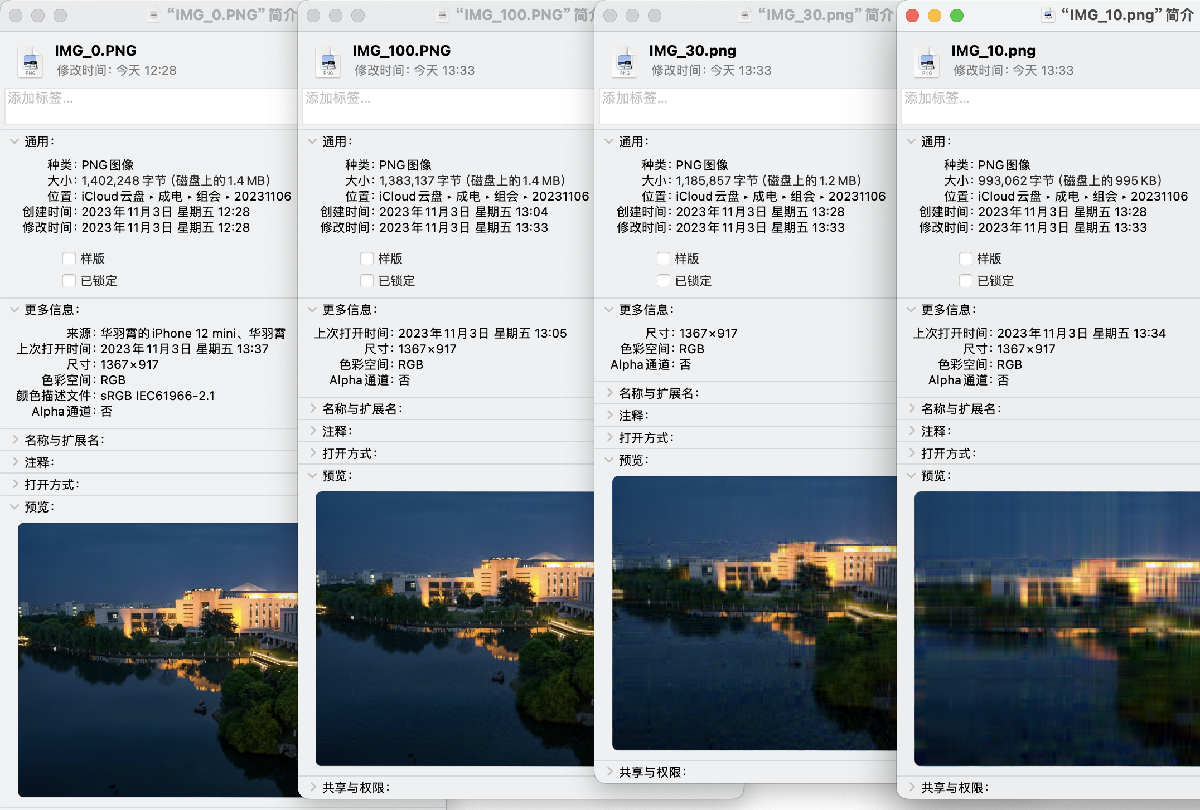

### 主成分分析（PCA）

    在机器学习和数据分析中，矩阵的秩经常用于降维技术，如主成分分析（PCA）。通过计算数据的协方差矩阵的秩（舍弃部分重要程度较低的特征值），可以找到数据中的主要特征，从而减少数据的维度，提高数据处理效率。

% 一个包含身高、体重、年龄、收入、教育水平和工作经验的数据集
data = [170 65 30 50000 16 5; 
        160 55 25 42000 14 4; 
        180 75 35 60000 18 6; 
        175 70 28 55000 16 5; 
        165 60 23 40000 12 3; 
        190 80 40 70000 20 8];
% 标注坐标轴
feature_labels = {'身高', '体重', '年龄', '收入', '教育水平', '工作经验'};

    原始数据各个变量单位不统一，需要消除量纲的影响，避免偏态数据的影响，并提高结果的稳定性和准确性。

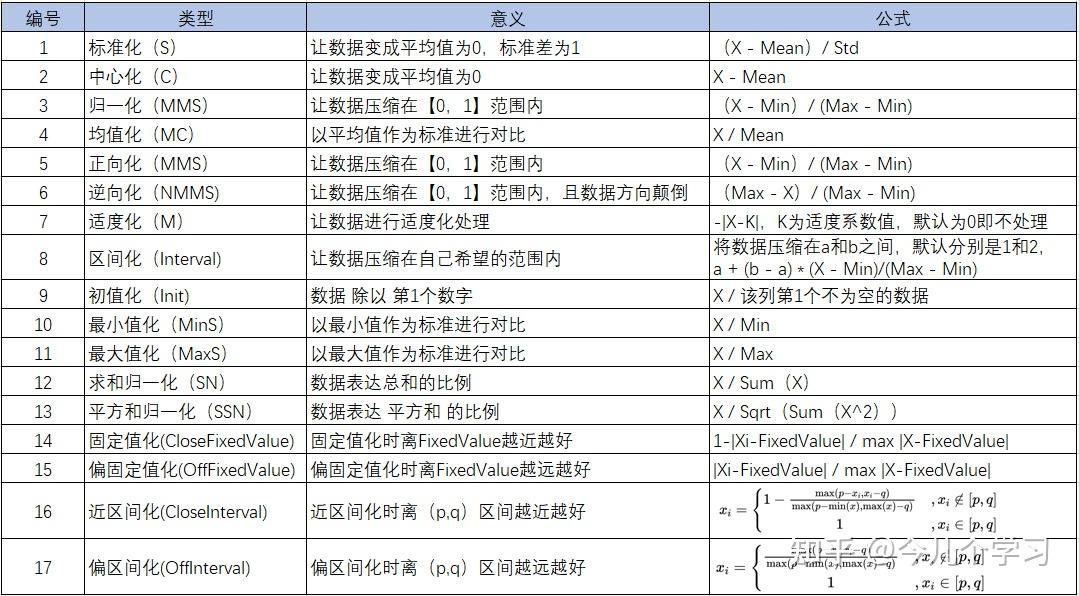

% 对数据进行标准化，确保每个特征的均值为0，方差为1
data_std = zscore(data)

data_std =    -0.3086   -0.2673   -0.0262   -0.2503         0   -0.0968
   -1.2344   -1.3363   -0.8112   -0.9569   -0.7071   -0.6773
    0.6172    0.8018    0.7589    0.6330    0.7071    0.4838
    0.1543    0.2673   -0.3402    0.1914         0   -0.0968
   -0.7715   -0.8018   -1.1252   -1.1336   -1.4142   -1.2579
    1.5430    1.3363    1.5439    1.5163    1.4142    1.6450


    **标准化（Standardization，Z-score normalization）**这种处理方式可以保持异常值中的有用信息，使得算法**对异常值不太敏感**（仍然会受到离群值的影响，但是相比于**归一化（Normalization，Min-Max Scaling）**，影响会小一点）。

[3] [(3 封私信 / 1 条消息) 主成分分析之前对原始数据进行均值化、标准化还是归一化？ - 知乎 (zhihu.com)](https://www.zhihu.com/question/54094066)

[4] [数据预处理：归一化和标准化 - 知乎 (zhihu.com)](https://zhuanlan.zhihu.com/p/296252799)

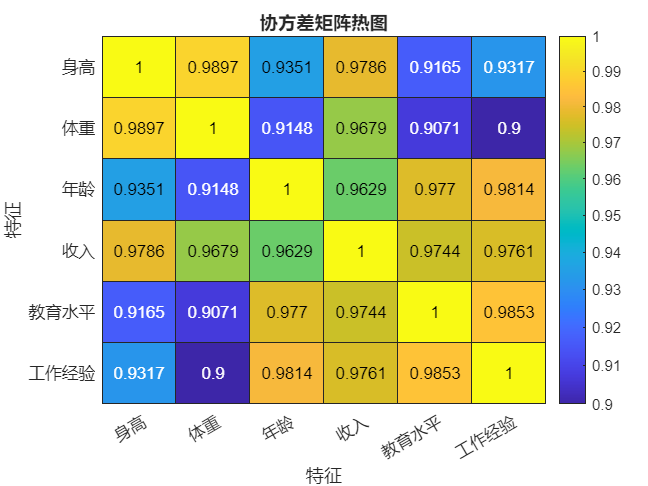

% 协方差矩阵表示了特征之间的线性关系
cov_matrix = cov(data_std);

% 创建热图
figure;
h = heatmap(cov_matrix, 'Colormap', parula, 'ColorScaling', 'log');

h.XDisplayLabels = feature_labels;
h.YDisplayLabels = feature_labels;
xlabel('特征'); ylabel('特征');
title('协方差矩阵热图');

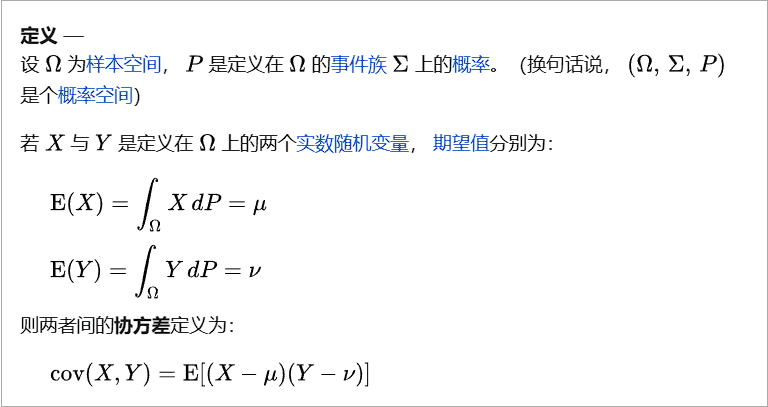

[5] [协方差 - 维基百科，自由的百科全书 (wikipedia.org)](https://zh.wikipedia.org/zh-cn/%E5%8D%8F%E6%96%B9%E5%B7%AE#%E5%AE%9A%E7%BE%A9)

% 特征向量代表主成分，特征值表示每个主成分的重要性
[V, D] = eig(cov_matrix)

V =     0.5961    0.2362    0.4004   -0.2145   -0.4656    0.4072
   -0.5162    0.1930   -0.4206    0.0496   -0.5961    0.4020
   -0.0000   -0.2890   -0.2806   -0.7551    0.3171    0.4086
   -0.0000   -0.7797    0.1860    0.4250   -0.0685    0.4149
    0.3902    0.3126   -0.4688    0.4459    0.4062    0.4079
   -0.4753    0.3433    0.5741    0.0433    0.3970    0.4089


D =    -0.0000         0         0         0         0         0
         0    0.0006         0         0         0         0
         0         0    0.0225         0         0         0
         0         0         0    0.0302         0         0
         0         0         0         0    0.1799         0
         0         0         0         0         0    5.7667



eigenvalues = diag(D);
% 按特征值降序排列
[sorted_eigenvalues, index] = sort(eigenvalues, 'descend')

sorted_eigenvalues =     5.7667
    0.1799
    0.0302
    0.0225
    0.0006
   -0.0000


index =      6
     5
     4
     3
     2
     1



% 选取协方差矩阵的最大的三个特征值对应的特征向量
selected_components = V(:, index(1:3))

selected_components =     0.4072   -0.4656   -0.2145
    0.4020   -0.5961    0.0496
    0.4086    0.3171   -0.7551
    0.4149   -0.0685    0.4250
    0.4079    0.4062    0.4459
    0.4089    0.3970    0.0433
